clc;
clear all;
close all;

#### Loading Data

folders=addpath('SH_functions','data');

Choose measured data

load('IRs_F.mat')
IRs(:,:,1)=IRs_F.GroundTruth; % Ground truth IRs of furnished reverberation room F
IRs(:,:,2)=IRs_F.Predicted;   % IRs generated by ESC predicted by the proposed method
IRs(:,:,3)=IRs_F.Predicted_05;% IRs generated by ESC =0.5

#### To plot

% Which 1/3 octave band to plot
plotOctaveBand=9;

#### Basic parameters

% Number of the scenarios
nScenarios=size(IRs,3);
% Speed of sound (m/s)
c0 = 343;
% Length of the signals
nSamplesSignal=length(IRs);
% Sampling frequency (Hz)
fs = nSamplesSignal-1;
% Time vector
tv = (0:1:nSamplesSignal-1) * (1 / fs);
% Min frequency
fMin=200;
% Max frequency
fMax=2500;

#### Equation to calculate sound pressure level

spl = @(input)(20 * log10(abs(input)))+120;

#### Fourier transform

TFs=fft(IRs,[],1);
TFsValid=TFs(1:fMax+1,:,:);

#### Plane wave density function (PWD)

% To calculate PWD on those directions
N_q=21;
dAngle=pi/(N_q-1);
th_q_p=0:dAngle:pi;
ph_q_p=0:dAngle:2*pi;
[phi_q,theta_q]=meshgrid(ph_q_p,th_q_p);
ph_q=reshape(phi_q,1,[]);
th_q=reshape(theta_q,1,[]);
nDirections=length(th_q);
% radius of Zylia ZM-1
rm=0.049; 
% Hard sphere
sphere=1;
% To calculate PWD
for iScenario = 1:nScenarios
for iFrequency=fMin+1:fMax
k=2*pi*(iFrequency-1)/c0;
kr=k*rm;
if kr>=1
N_bar=3;
else if kr>=0.55
N_bar=2;
else 
N_bar=1;
end
end
% SH function of sampled sphere
Ys=sh2(N_bar,th_s,ph_s);
% SH function of reconstructed sphere
Yq=sh2(N_bar,th_q,ph_q);
B=BnMat(N_bar,kr,kr,sphere);
soundField=reshape(TFsValid(iFrequency,:,iScenario),1,[]);
% Spherical Fourier transform
thisPnm=(soundField*Ys');  
% Reconstruct plane wave density function
thisPWD=reshape((thisPnm./B)*Yq,1,[]);
PWD(iScenario,:,:,iFrequency)=thisPWD;
%% Reconstruct sound field on open sphere
% B0=BnMat(N_bar,kr,kr,0);
% thisReSoundField=reshape((thisPnm./B.*B0)*Yq,1,[]);
% ReSoundField(iScenario,:,:,iFrequency)=thisReSoundField;
end
end

#### IRs of the PWD

%Zero padding so the IRs_PWD will have the sampling rate of fs
PWDpadding=cat(4,PWD,zeros(nScenarios,1,nDirections,fs/2-fMax));
% Fourier Transform
PWD_Symmetric=cat(4,PWDpadding,conj(PWDpadding(:,:,:,end:-1:2)));
% Inverse Fourier Transform
IRs_PWD=ifft(PWD_Symmetric,[],4);

#### To define time window (to chop signals)

% Mean free path length 
meanFreePathLength = 4 * volume ./ surfaceArea;
% Approximate reflection order
order = (1./meanFreePathLength)*tv * c0 ;
% Each short signal contains one reflection 
nReflection = 1;
% Number of short signals
tMax =max(tv);
nSegment = floor(tMax/(nReflection * (meanFreePathLength/ c0)));
% Points of each short signal contains
nChoppedIR = floor(nSamplesSignal/nSegment);
% Time vector for each short signal
tSegment=nChoppedIR*(0.5:nSegment-0.5)/fs;
% Length of each segment
dSegment=nChoppedIR/fs;

#### To chop signals

% Max order of the short signal
maxOrder=10;
% Order vector
nOrder=0:maxOrder;
% To chop signals using a rectangular window
choppedIRs=cat(4,reshape(IRs_PWD(:,:,:,1:(maxOrder+1)*nChoppedIR),nScenarios,1,nDirections,nChoppedIR,(maxOrder+1)),zeros(nScenarios,1,nDirections,fs/10-nChoppedIR,maxOrder+1));
% Frequency resolution of the chopped signal
resFrequency=1/(length(choppedIRs)/fs);
% Number of frequency points
nFrequency=fMax/resFrequency+1;
% Frequency vector of the chopped signal
fChopped=0:resFrequency:(nFrequency-1)*resFrequency;
% Fourier Transform 
choppedSTFs=fft(choppedIRs,[],4)/(fs/10);% symmetric transfer function
choppedTFs=choppedSTFs(:,:,:,1:nFrequency,:);% single side transfer function

#### 1/3rd octave band

% Center frequency of the filter 
centerFrequenciesValid=[315  400  500    630    800   1000   1250    1600   2000];
plotcenterFrequency=centerFrequenciesValid(plotOctaveBand) 

plotcenterFrequency = 2000

% Lower frequency of 1/3rd octave band
fl = 10*round(plotcenterFrequency * 2^(-1/6)/10);
% Upper frequency of 1/3rd octave band
fu = 10*round(plotcenterFrequency * 2^(1/6)/10);

#### PWD averaged over frequency in this 1/3rd octave band for each segment

for iSegment=1:maxOrder+1
% Ground truth PWD of furnished reverberation room F
PWDGroundTruth(:,:,iSegment)=reshape(mean(abs(choppedTFs(1,:,:,fl/10:fu/10,iSegment)),4),N_q,2*(N_q-1)+1);
% PWD generated by ESC predicted by the proposed method
PWDPredicted(:,:,iSegment)=reshape(mean(abs(choppedTFs(2,:,:,fl/10:fu/10,iSegment)),4),N_q,2*(N_q-1)+1);
% pwd generated by ESC =0.5
PWDPredicted_05(:,:,iSegment)=reshape(mean(abs(choppedTFs(3,:,:,fl/10:fu/10,iSegment)),4),N_q,2*(N_q-1)+1);
% Maximum value of all
maxPWD(:,iSegment)=max(max([PWDGroundTruth(:,:,iSegment),PWDPredicted(:,:,iSegment),PWDPredicted_05(:,:,iSegment)]));
end

#### Normalization

PWDGroundTruth_Normal=PWDGroundTruth/max(maxPWD);
PWDPredicted_Normal=PWDPredicted/max(maxPWD);
PWDPredicted_05_Normal=PWDPredicted_05/max(maxPWD);

#### Plot plane wave density function

% Plot from order 0 to 2  
maxPlot=3;
% The span for contourf
ValLines=(0:0.1:1);

#### Ground truth PWD    [FIG.15(a)]

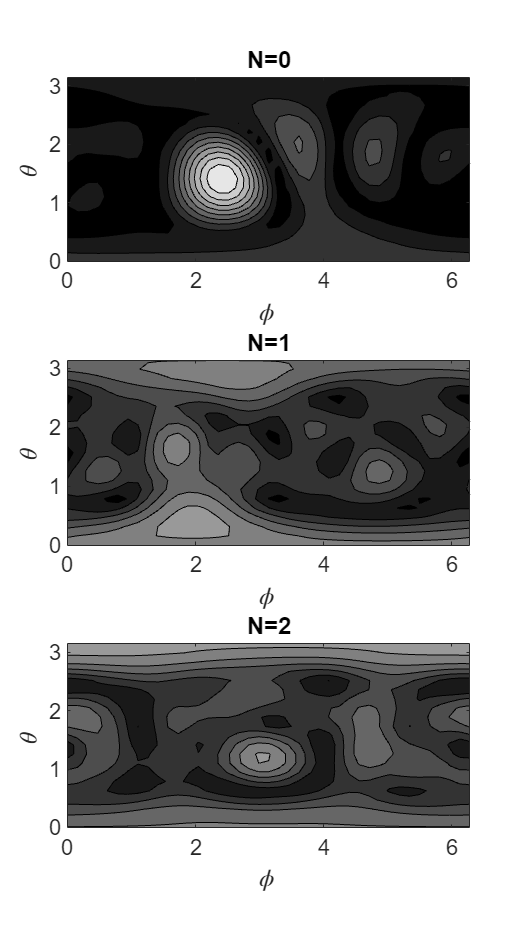

figure
for iPlot = 1:maxPlot
    subplot(maxPlot,1,iPlot)
plotSegment=iPlot; 
[C,h]=contourf(ph_q_p,th_q_p,PWDGroundTruth_Normal(:,:,plotSegment),ValLines);
caxis([0,1]);
colormap(gray);
xlabel('$\phi\,$','Interp','Latex');  ylabel('$\theta\,$','Interp','Latex'); 
title(['N=' num2str(iPlot-1)]);
set(gca,'FontSize',13);
end
set(gcf,'Units','centimeters','Position',[5 2 11 20]);

#### PWD generated by the ESC calculated by proposed method     [FIG.15(b)]

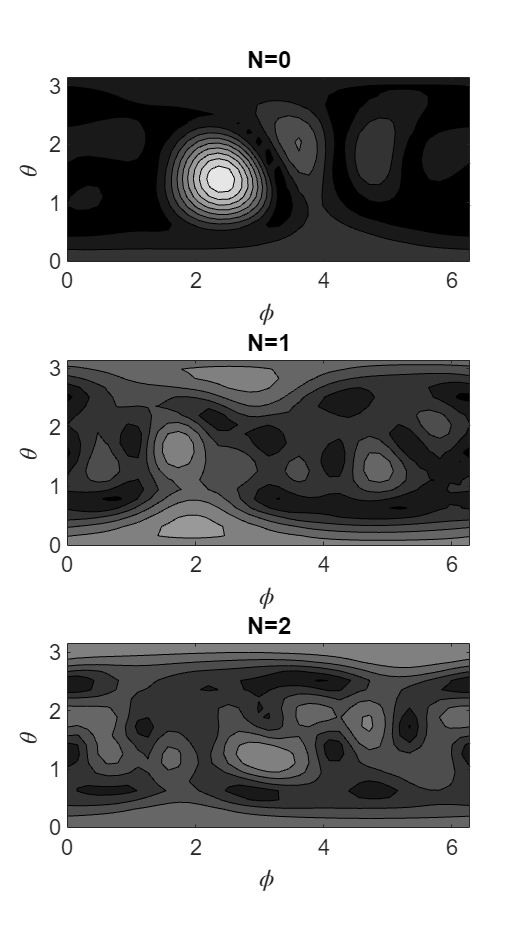

figure
for iPlot = 1:maxPlot
    subplot(maxPlot,1,iPlot)
plotSegment=iPlot;  
[C,h]=contourf(ph_q_p,th_q_p,PWDPredicted_Normal(:,:,plotSegment),ValLines);
caxis([0,1]);
colormap(gray);
xlabel('$\phi\,$','Interp','Latex');  ylabel('$\theta\,$','Interp','Latex'); 
title(['N=' num2str(iPlot-1)]);
set(gca,'FontSize',13);
end
set(gcf,'Units','centimeters','Position',[17 2 11 20]);

#### PWD generated by the ESC = 0.5     [FIG.15(c)]

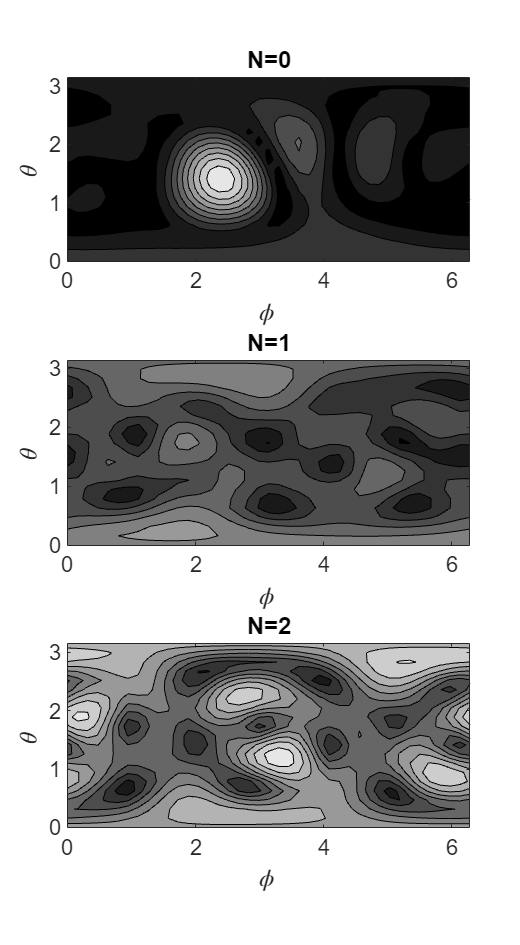

figure
for iPlot = 1:maxPlot
    subplot(maxPlot,1,iPlot)
plotSegment=iPlot;  
[C,h]=contourf(ph_q_p,th_q_p,PWDPredicted_05_Normal(:,:,plotSegment),ValLines);
caxis([0,1]);
colormap(gray);
xlabel('$\phi\,$','Interp','Latex');  ylabel('$\theta\,$','Interp','Latex'); 
title(['N=' num2str(iPlot-1)]);
set(gca,'FontSize',13);
end
set(gcf,'Units','centimeters','Position',[29 2 11 20]);